syms rw r2 r3 r5 l7_ab I7 m1 m2 m3 m4 m5 m6 m7 I1 I2 I3 I4 I5 I6 g2 C_friction7 ta13 a51 tv13 t13 T_z height1 length1 wheel_density frame_density gear_density gear_thickness frame_thickness wheel_thickness
load flip_eqns.mat
load roll_eqns.mat
load design_parameters.mat


%apply to eqs
Q_eqn=subs(flip_eqns(1), lhs(design_parameters), rhs(design_parameters));
Q_eqn= ta13 == simplify(rhs(Q_eqn))


%R_eqn=subs(roll_eqns, lhs(design_parameters), rhs(design_parameters))
%R_eqn= lhs(R_eqn) == simplify(rhs(R_eqn))

testeqn= ta13 == simplify(rhs(subs(Q_eqn, [tv13], [0])))

testeqn= ta13 == simplify(rhs(subs(testeqn, [t13], [0])))

$$testeqn = {\mathrm{ta}}_{13}=\frac{29442421196058601846629151539200000000\,T_{z}+811382653092554516895797084160000000\,\sqrt{247}\,T_{z}-41087833061151693454689777399889920\,\sqrt{247}-22082808055875463394235816010894540800}{370326269990700095977078879108131\,\sqrt{247}+7192430893145724697884065252082761190}$$


%testeqn2= ta13 == rhs(subs(R_eqn(1), [tv13], [0]))
%testeqn2= ta13 == rhs(subs(testeqn2, [t13], [0]))
%testeqn2= ta13 == simplify(rhs(testeqn2))

%create plot of required torque vs position
P_eqn=subs(Q_eqn, [tv13, ta13], [0, 0])

P_eqn=isolate(P_eqn, T_z)

$$P\_eqn = \begin{array}{l} T_{z}=\frac{\frac{37115474200747379341394574311424\,\sin\left(2\,t_{13}\right)\,\sigma_{1}}{5}+10031209243445237659836371435520\,\cos\left(t_{13}\right)\,\sigma_{3}+873086730448011425948721217536\,\cos\left(t_{13}\right)\,\sigma_{2}+46440783534468692869612830720\,\sin\left(t_{13}\right)\,\sigma_{2}}{1164063338027367545176064000000\,\sigma_{2}+8730475035205256588820480000000\,\sigma_{1}+189360993004969186012692480000000\,\cos\left(t_{13}\right)\,\sigma_{3}-6014996248393138849814937600000\,\sin\left(t_{13}\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}={\left(-12321\,{\sin\left(t_{13}\right)}^{2}-16650\,\sin\left(t_{13}\right)+154375\right)}^{3/2}\\ \sigma_{2}={\left(12321\,{\sin\left(t_{13}\right)}^{2}+16650\,\sin\left(t_{13}\right)-154375\right)}^{2}\\ \sigma_{3}={\left(12321\,{\cos\left(t_{13}\right)}^{2}-16650\,\sin\left(t_{13}\right)+142054\right)}^{3/2} \end{array}$$

xvals=linspace(0, pi/2, 100)

xvals =          0    0.0159    0.0317    0.0476    0.0635    0.0793    0.0952    0.1111    0.1269    0.1428    0.1587    0.1745    0.1904    0.2063    0.2221    0.2380    0.2539    0.2697    0.2856    0.3015    0.3173    0.3332    0.3491    0.3649    0.3808    0.3967    0.4125    0.4284    0.4443    0.4601    0.4760    0.4919    0.5077    0.5236    0.5395    0.5553    0.5712    0.5871    0.6029    0.6188    0.6347    0.6505    0.6664    0.6823    0.6981    0.7140    0.7299    0.7457    0.7616    0.7775


yvals = linspace(0, 0, 100)

yvals =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


syms Tf(t13)
Tf(t13) = rhs(P_eqn)

$$Tf(t13) = \begin{array}{l} \frac{\frac{37115474200747379341394574311424\,\sin\left(2\,t_{13}\right)\,\sigma_{1}}{5}+10031209243445237659836371435520\,\cos\left(t_{13}\right)\,\sigma_{3}+873086730448011425948721217536\,\cos\left(t_{13}\right)\,\sigma_{2}+46440783534468692869612830720\,\sin\left(t_{13}\right)\,\sigma_{2}}{1164063338027367545176064000000\,\sigma_{2}+8730475035205256588820480000000\,\sigma_{1}+189360993004969186012692480000000\,\cos\left(t_{13}\right)\,\sigma_{3}-6014996248393138849814937600000\,\sin\left(t_{13}\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}={\left(-12321\,{\sin\left(t_{13}\right)}^{2}-16650\,\sin\left(t_{13}\right)+154375\right)}^{3/2}\\ \sigma_{2}={\left(12321\,{\sin\left(t_{13}\right)}^{2}+16650\,\sin\left(t_{13}\right)-154375\right)}^{2}\\ \sigma_{3}={\left(12321\,{\cos\left(t_{13}\right)}^{2}-16650\,\sin\left(t_{13}\right)+142054\right)}^{3/2} \end{array}$$

%fplot(Tf(t13), [0, pi/2])

%for i = 1:100
%    yvals=rhs(subs(P_eqn, t13, xvals(i)))
%end
%plot(xvals, yvals)

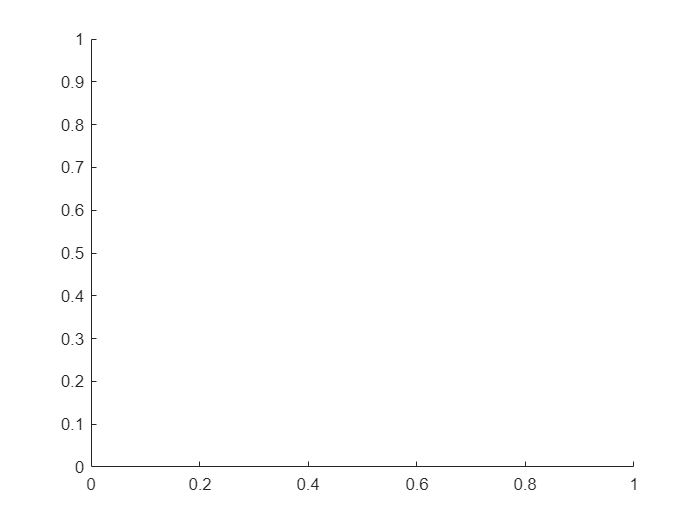


hold off


xvals=zeros(length(design_parameters),100)

xvals =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

yvals=zeros(length(design_parameters),100)

yvals =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

yvals2=zeros(length(design_parameters),100)

yvals2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

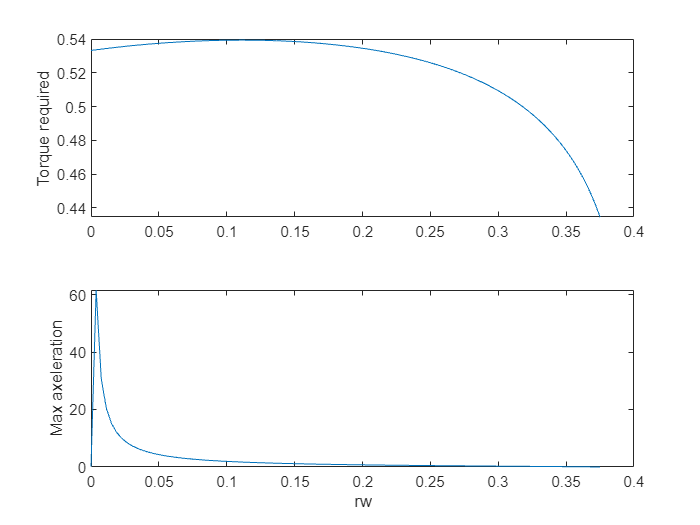

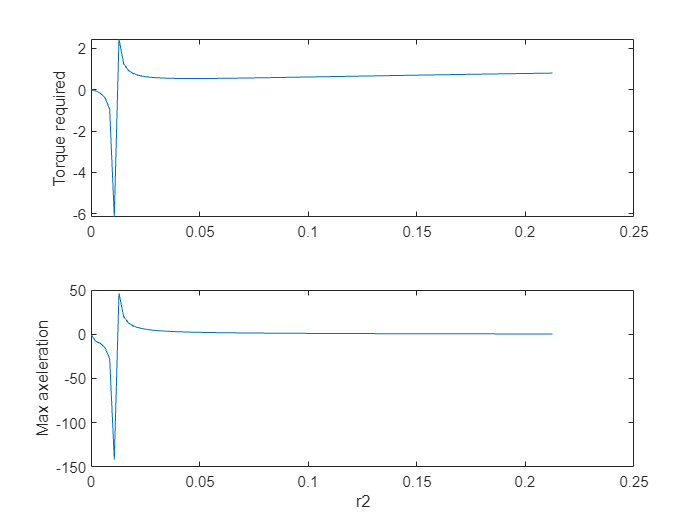

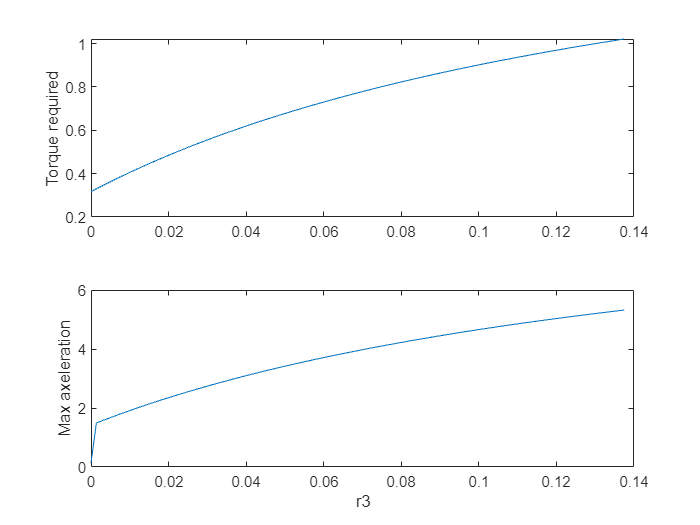

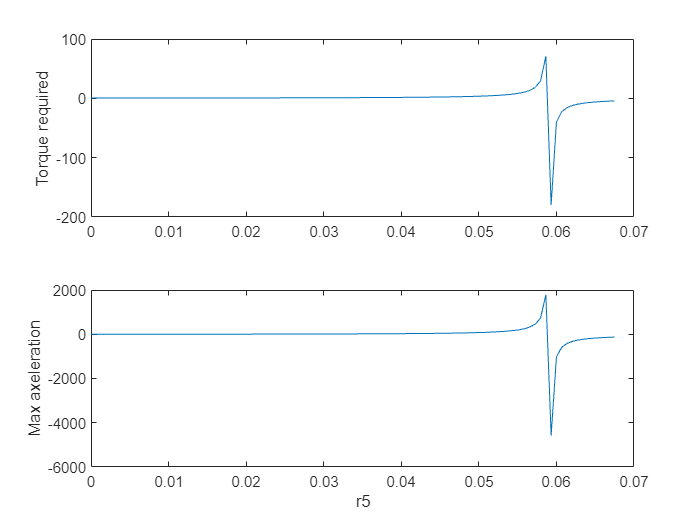

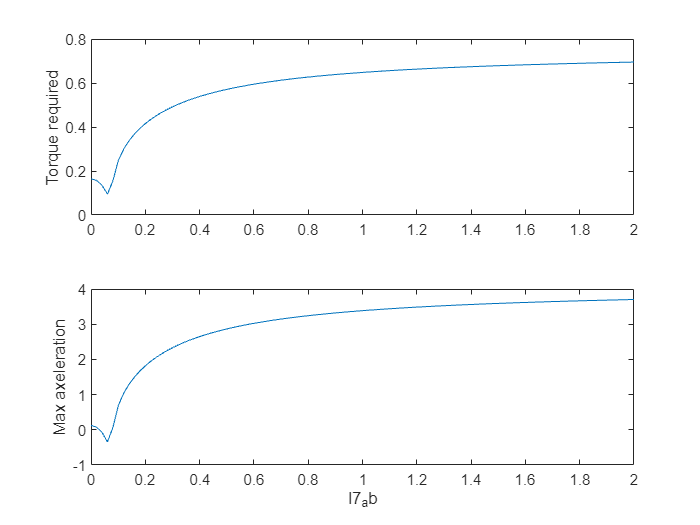

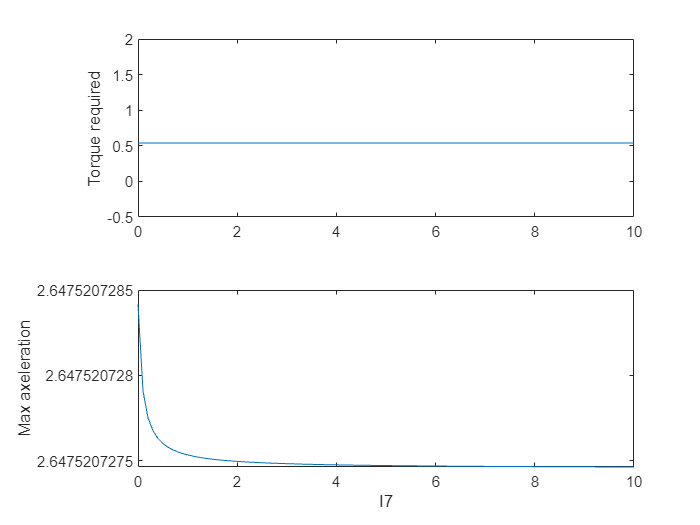

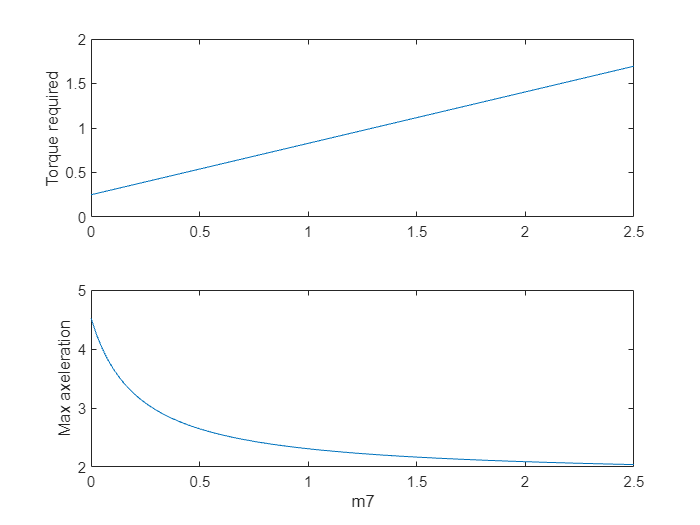

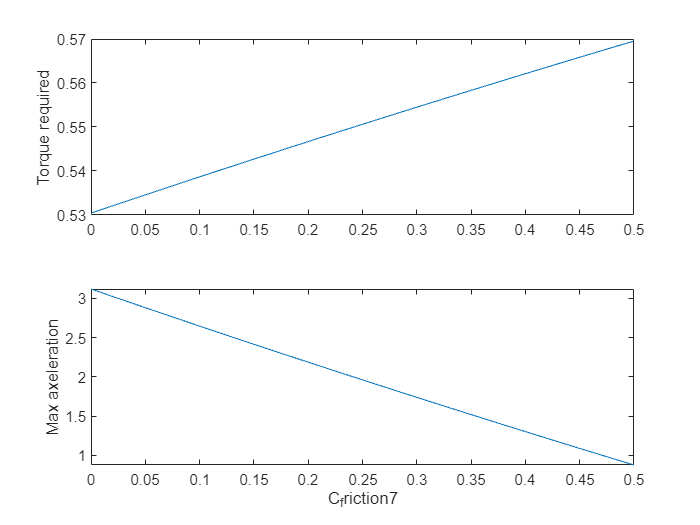


Q_eqn=subs(flip_eqns(1), lhs(derived_parameters), rhs(derived_parameters));
R_eqn=subs(roll_eqns(2), lhs(derived_parameters), rhs(derived_parameters));

for i=1:length(design_parameters)
    P_eqn=subs(Q_eqn, lhs(design_parameters(1:end ~=i)), rhs(design_parameters(1:end ~=i)));
    P_eqn=subs(P_eqn, [tv13, ta13, t13], [0, 0, 0]);
    P_eqn=isolate(P_eqn, T_z);
    xvals(i,:)=linspace(1e-10, 5*rhs(design_parameters(i)), 100);

    for k = 1:100
        try
            yvals(i,k)=real(double(rhs(subs(P_eqn, lhs(design_parameters(i)), xvals(i,k)))));
        catch 
        end
    end

    P_eqn=subs(R_eqn, lhs(design_parameters(1:end ~=i)), rhs(design_parameters(1:end ~=i)));
    P_eqn=subs(P_eqn, [tv13, ta13, t13], [0, 0, 0]);
    %P_eqn=isolate(P_eqn, T_z);
    for k = 1:100
        try
            yvals2(i,k)=real(double(rhs(subs(P_eqn, [lhs(design_parameters(i)),T_z], [xvals(i,k), yvals(i,k)]))));
        catch 
        end
    end
    figure
    hold on
    tiledlayout(2,1)
    nexttile
    plot(xvals(i,:), yvals(i,:))
    ylabel("Torque required")
    nexttile
    plot(xvals(i,:), yvals2(i,:))
    ylabel("Max axeleration")
    xlabel(string(lhs(design_parameters(i))))
    hold off
end    